# MATLAB绘图

## 1、二维绘图命令plot

绘制$y=\sin \left(x\right)$

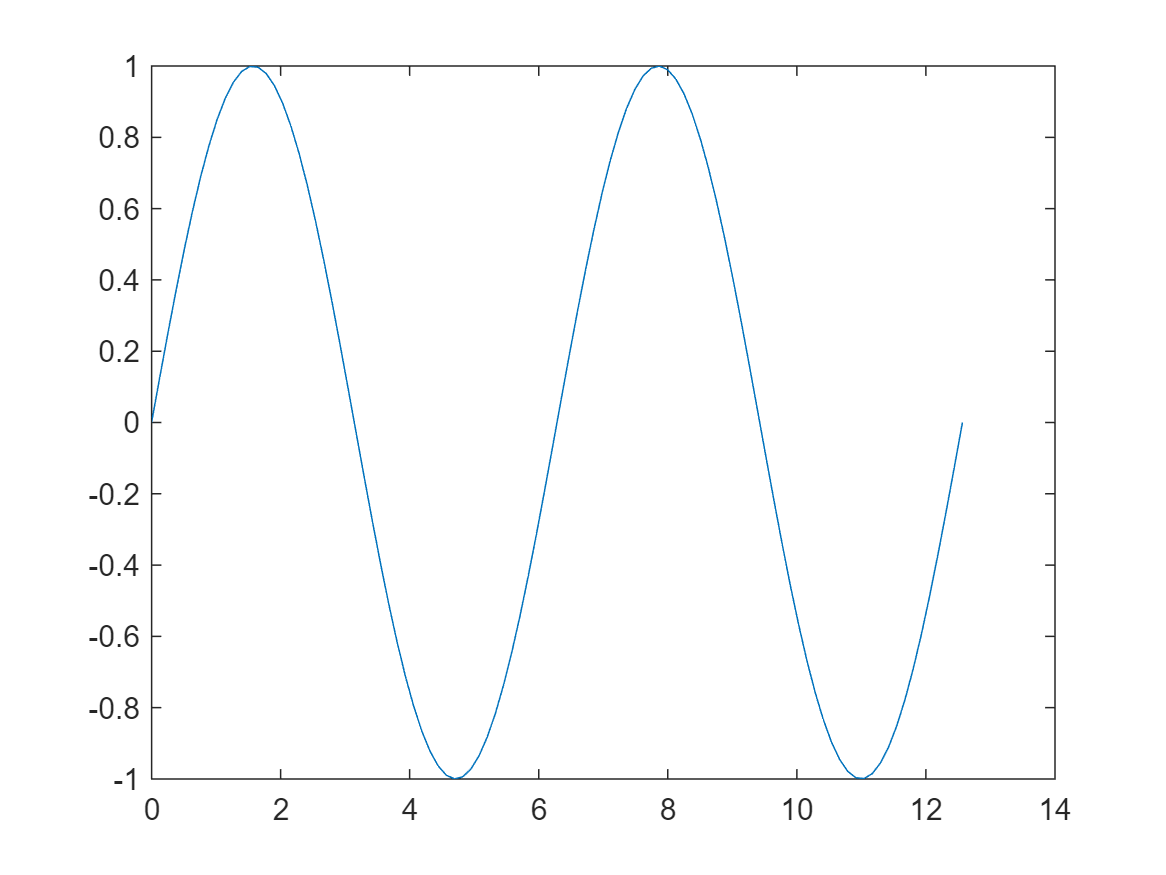

x = linspace(0, 4*pi, 100);
y1 = sin(x);
plot(x, y1);

## 2、同一坐标绘制多条曲线

方法1：hold

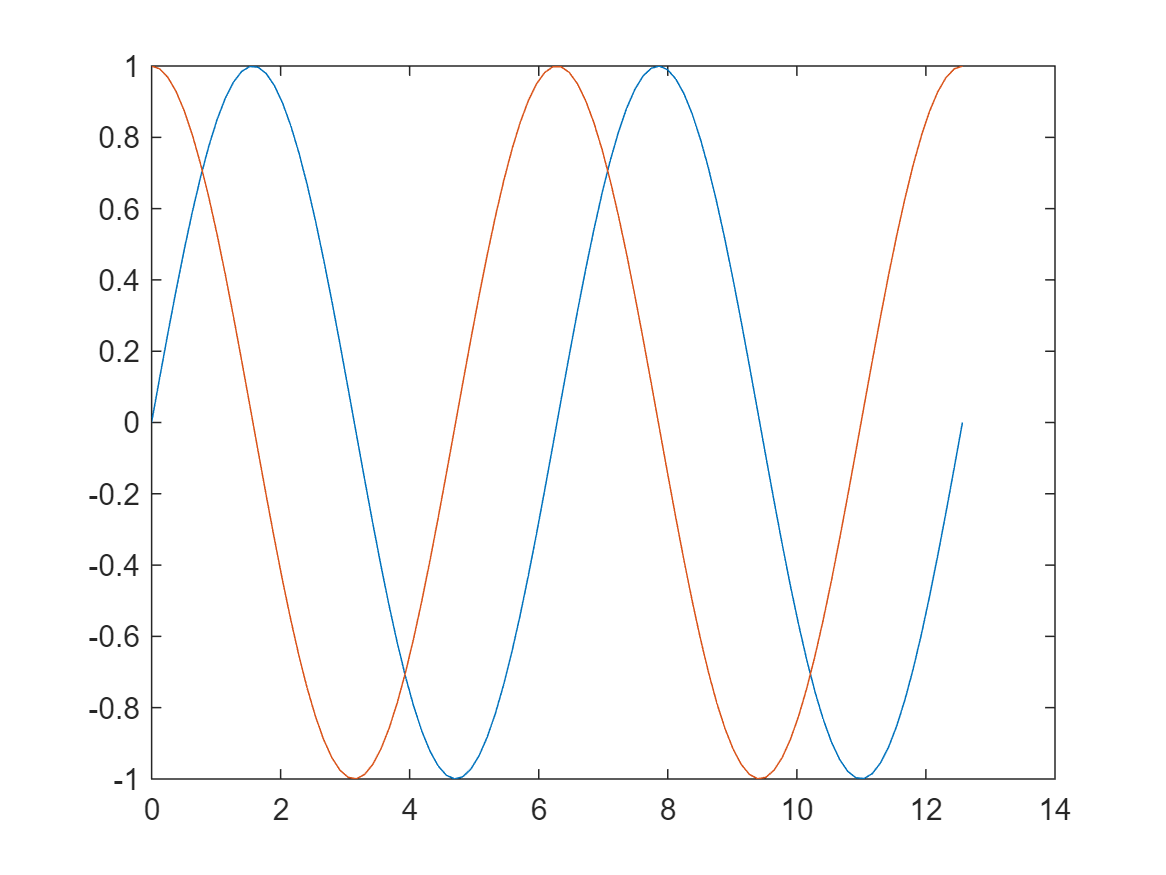

% hold on   开启图形保持功能，绘制多个图像
% hold off  关闭图形保持功能
x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);

plot(x, y1);
hold on;
plot(x, y2);
hold off;

方法2：plot(x1, y1, x2, y2, ...)

plot(x, y1, x, y2);

## 3、添加轴标签(label)、标题(title)、图例(legend)

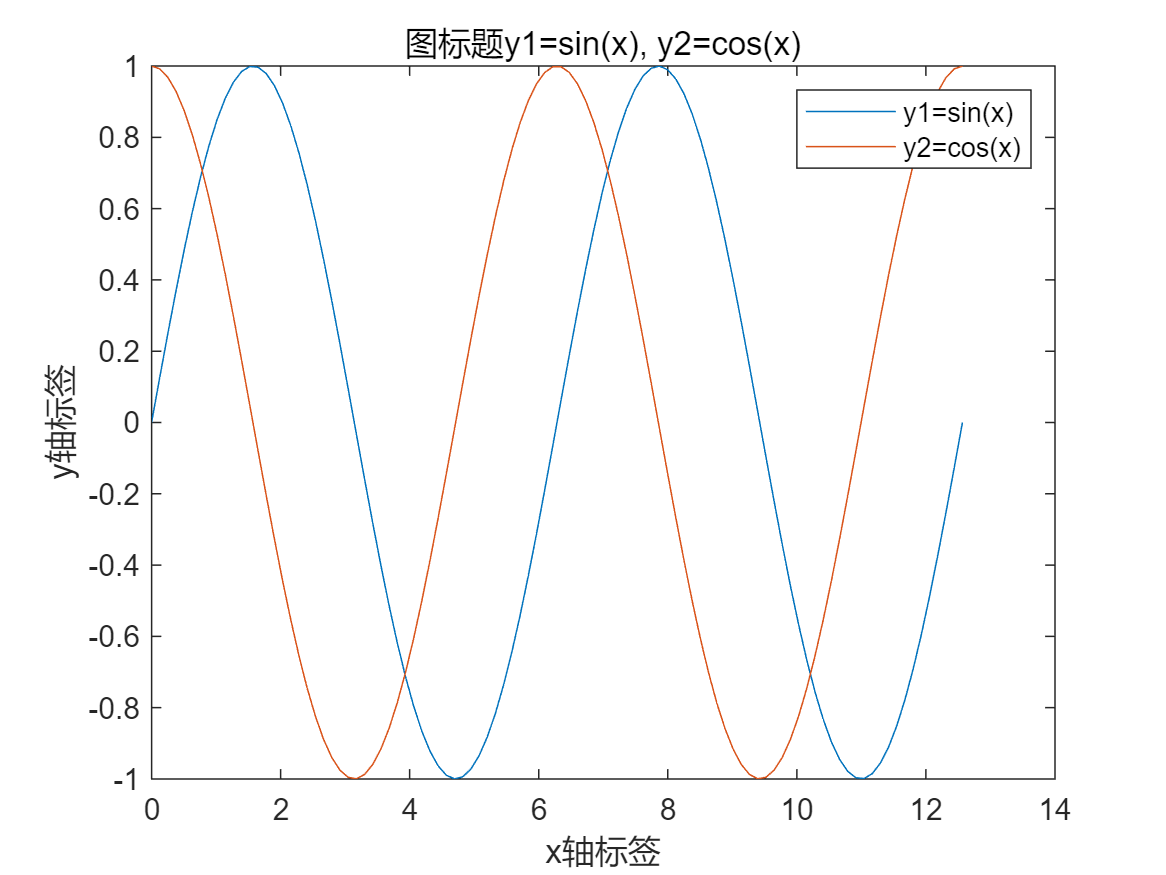

x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);

plot(x, y1, x, y2);
xlabel('x轴标签');
ylabel('y轴标签');
title('图标题y1=sin(x), y2=cos(x)');
legend('y1=sin(x)', 'y2=cos(x)')

## 4、绘制多个Figure窗口

x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);
figure;
plot(x, y1);

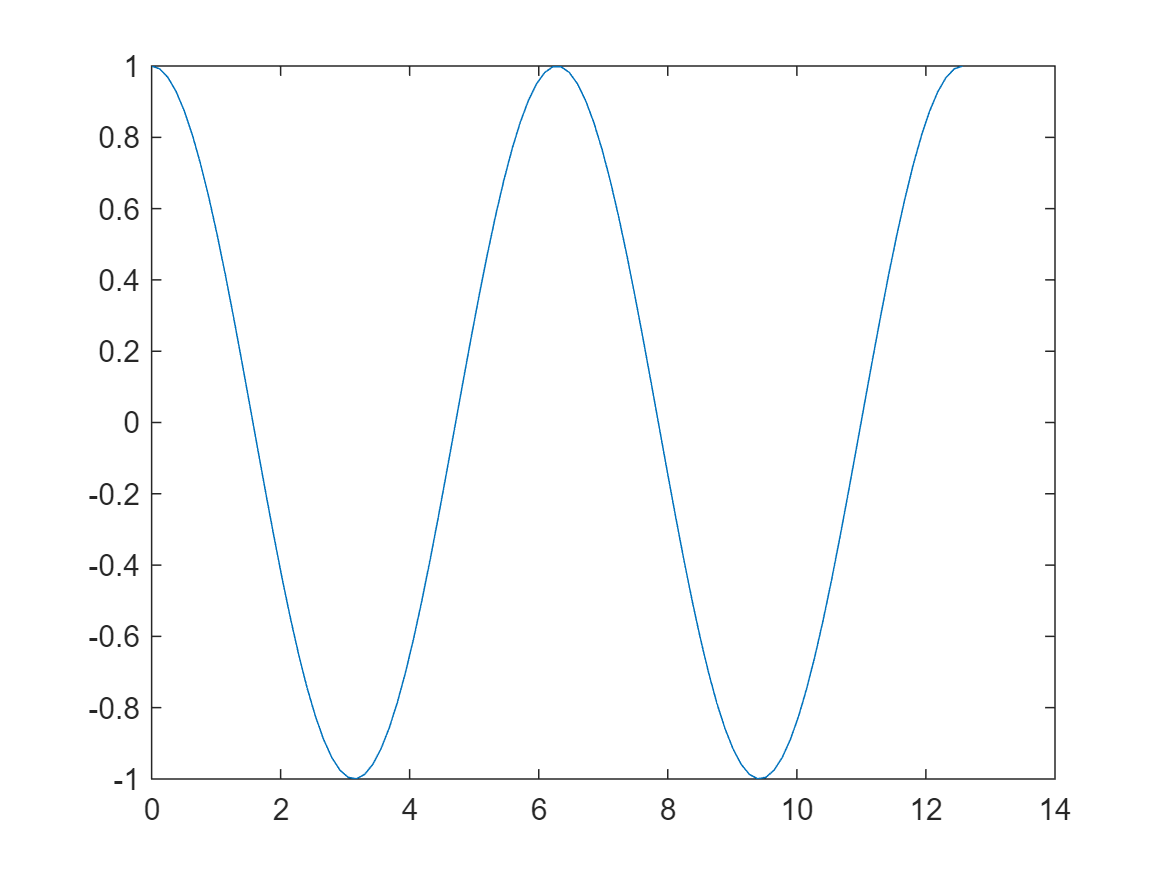

figure;
plot(x, y2);

## 5、绘制多个子图subplot

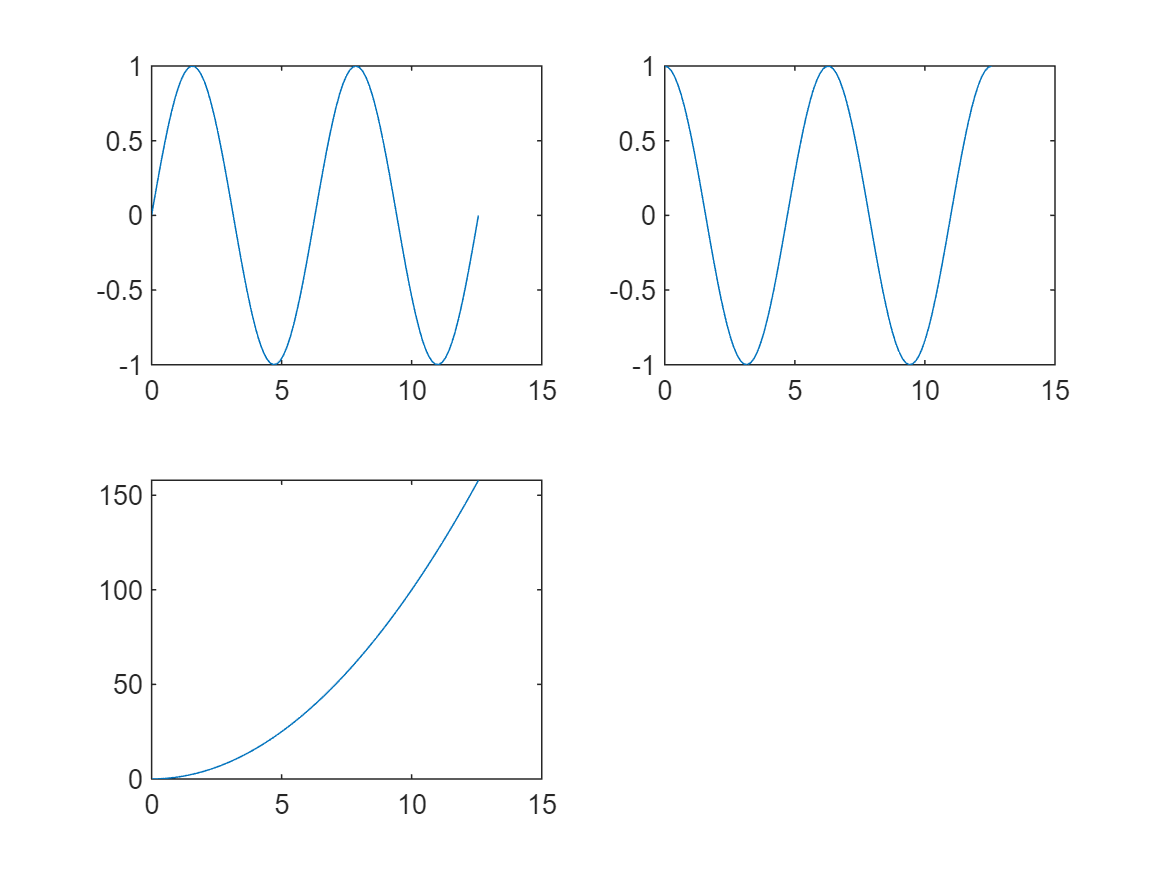

% subplot(m, n, i)    m行n列，第i个图形
x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);
y3 = x.^2;

subplot(2,2,1);
plot(x, y1);
subplot(2,2,2);
plot(x, y2);
subplot(2,2,3);
plot(x, y3);